# Bandpass the FRF and preserve the Conjugate symmetry about the Nyquist

Consider 2 different REAL signals

- $e\left(t\right)$ has an EVEN number of samples

-  $d\left(t\right)$ has an ODD number of samples

Let's say we compute the FFT of each of these signals

- 
$$e\left(t\right)$$
 
$$\longrightarrow \;\;E$$


- 
$$d\left(t\right)$$
 
$$\longrightarrow \;D$$


$E$ and $D$ will exhibit conjugate symmetry shapes similar to those shown below

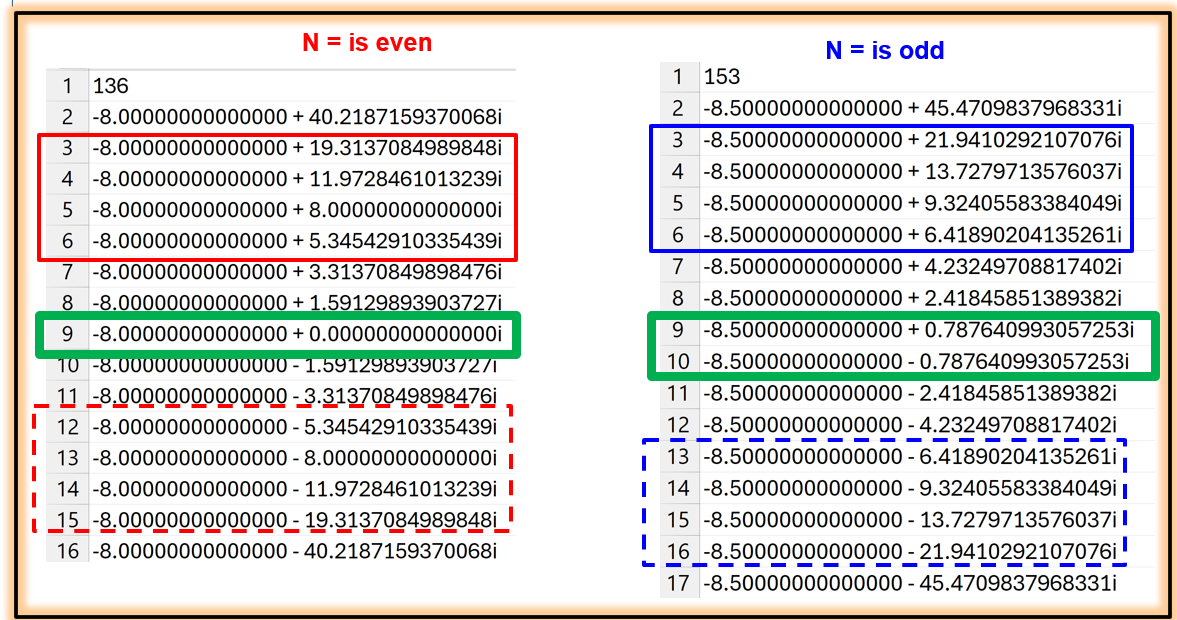

###  Consider first the EVEN case with N=16

- 
$$k=3:\;\;E\left(3\right)=\mathrm{conj}\left(\;\;E\left(g\right)\;\right)\;\;\;\;\;\mathrm{where}\;\;\;\;g=15=16+2-3$$


- 
$$k=4:\;\;E\left(4\right)=\mathrm{conj}\left(\;\;E\left(g\right)\;\right)\;\;\;\;\;\mathrm{where}\;\;\;\;g=14=16+2-4$$
  

- 
$$k=5:\;\;E\left(5\right)=\mathrm{conj}\left(\;\;E\left(g\right)\;\right)\;\;\;\;\;\mathrm{where}\;\;\;\;g=13=16+2-5$$
 

- 
$$k=6:\;\;E\left(5\right)=\mathrm{conj}\left(\;\;E\left(g\right)\;\right)\;\;\;\;\;\mathrm{where}\;\;\;\;g=12=16+2-6$$
 

So to preserve the conjugate symmetry we have

- 
$$E\left(k\right)=\mathrm{conj}\left(\;\;E\left(N+2-k\right)\;\;\right)\;\;\;\;\;$$
 

### Consider first the ODD case with N=17

- 
$$k=3:\;O\left(3\right)=\mathrm{conj}\left(\;\;O\left(g\right)\;\right)\;\;\;\;\;\mathrm{where}\;\;\;\;g=16=17+2-3$$


- 
$$k=4:\;O\left(4\right)=\mathrm{conj}\left(\;\;O\left(g\right)\;\right)\;\;\;\;\;\mathrm{where}\;\;\;\;g=15=17+2-4$$


- 
$$k=5:\;O\left(5\right)=\mathrm{conj}\left(\;\;O\left(g\right)\;\right)\;\;\;\;\;\mathrm{where}\;\;\;\;g=14=17+2-5$$


- 
$$k=6:\;O\left(5\right)=\mathrm{conj}\left(\;\;O\left(g\right)\;\right)\;\;\;\;\;\mathrm{where}\;\;\;\;g=13=17+2-6$$
 

So to preserve the conjugate symmetry we have

- 
$$O\left(k\right)=\mathrm{conj}\left(\;\;O\left(N+2-k\right)\;\;\right)\;\;\;\;\;$$
 

### So the General algorithm:

- 
$$Y\left(k\right)=\mathrm{conj}\left(\;\;Y\left(N+2-k\right)\;\;\right)$$
  

- or alternatively   $Y\left(N+2-k\right)=\mathrm{conj}\left(\;\;Y\left(k\right)\;\;\right)$

function new_frf = bh_bandpass_frf(frf_col, fhz_col, FMIN, FMAX)

    new_frf        = zeros( size(frf_col)  );

    ind            = find(fhz_col > FMIN & fhz_col < FMAX);
    FRF_CHUNK      = frf_col(ind);
    new_frf(ind)   = FRF_CHUNK;

    ind_b          = numel(frf_col) + 2 -ind;
    new_frf(ind_b) = conj(FRF_CHUNK);
end